# MATLAB-Python Workflow to Predict Masked SMILES Tokens Using BERT   

### Introduction

This example shows how to predict masked tokens using a pretrained [BERT](https://huggingface.co/transformers/v3.0.2/index.html) model. BERT models are trained to perform various tasks. One of the tasks is known as masked language modeling which is the task of predicting token in text that have been replaced by a mask value. This example shows how to predict masked tokens for text data and calculate the token probabilities using a pretrained BERT model.  

### Setting up the conda environment

This example uses some of the fucntions from [RDKit](https://www.rdkit.org/). We, therefore set the conda environment using these two lines. Make sure you give your python addess in the first line of "Setup_Conda_Environment.m" pyExec = '...\anaconda3\';

Setup_Conda_Environment;
!conda activate DeepChem-env

 Alternatively, you may install [DeepChem](https://deepchem.io/) by running the following commads. DeepChem will be used in other examples for some deep learing implementations.

*           conda install -c conda-forge rdkit deepchem==2.6.1*

*           pip install tensorflow~=2.4*

%% It is always a good practice to set up the workspace first:
clear;
clc;
close all;

### Input molecule and vizualize

Provide the SMILES sting. You can also provide the substructure you would like to highlight in the molecule.

SMILES="CCN(CC)C(=O)c1cccnc1";
Mask="CCN";
Masked_SMILES = "<mask>(CC)C(=O)c1cccnc1";

strfind(SMILES,Mask)

ans = 1

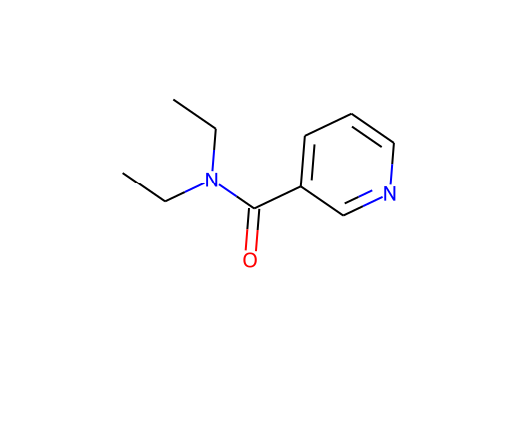

res0 = pyrunfile("ChemMolFromSmiles.py","mol0",x=SMILES);
img0 = string(res0);
rgbImage0 = imread(img0);
imshow(rgbImage0)

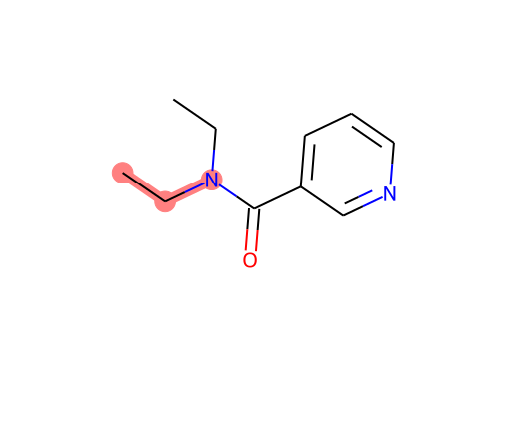

res1 = pyrunfile("GetSubstructMatch.py","mol1",x=SMILES,y=Mask);
img1 = string(res1);
rgbImage1 = imread(img1);
imshow(rgbImage1)

### Load Pretrained BERT Model

Load a pretrained BERT model using the |bert| function. The model consists of a tokenizer that encodes text as sequences of integers, and a structure of parameters.

Model = pyrunfile("Py_Chem_Model.py","moldel");
Tokenizer = pyrunfile("Py_Chem_Tokenizer.py","tokenizer");

### Predict Masked Token

Predict the masked token using the |predictMaskedToken| function. The function returns the original string with the mask tokens replaced.

pyrunfile("Py_Chem_Predict.py",smiles_mask=Masked_SMILES);

{'score': 0.3347172439098358, 'token': 267, 'token_str': 'CCC', 'sequence': 'CCC(CC)C(=O)c1cccnc1'}
{'score': 0.24358177185058594, 'token': 289, 'token_str': 'CCN', 'sequence': 'CCN(CC)C(=O)c1cccnc1'}
{'score': 0.13082949817180634, 'token': 293, 'token_str': 'CCCCC', 'sequence': 'CCCCC(CC)C(=O)c1cccnc1'}
{'score': 0.06048673018813133, 'token': 373, 'token_str': 'CCCCN', 'sequence': 'CCCCN(CC)C(=O)c1cccnc1'}
{'score': 0.040443334728479385, 'token': 621, 'token_str': 'CCOCCN', 'sequence': 'CCOCCN(CC)C(=O)c1cccnc1'}


### References

1) [Transformers: State-of-the-Art Natural Language Processing](https://aclanthology.org/2020.emnlp-demos.6/).